% Principal Component Analysis of whole brain using Aya's EEG dataset
% across time.
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
% 1- ICA on preprocessed epoched data
% What preprocessing has been done:
% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


% 2- PCA 
% - 2.1 PCA across space: across IC space

% For the BLA, BLT and P1, we choose the odd epochs to correspond with auditory onset. 
% Extract relevant parameters
fs = EEG.srate; % Sampling rate
time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)
epoch_trials = 1:2:EEG.trials; % Select odd trials
num_trials = length(epoch_trials);

% Define pre- and post-stimulus time windows (400ms before and after stimulus onset at 500ms)
% 512 sample/sec x 0.4 sec = 204.8
pre_window = [-0.4, 0];  % Pre-stimulus window (-400ms to 0ms)
post_window = [0, 0.4];  % Post-stimulus window (0ms to +400ms)

% Convert time to indices
pre_idx = find(time_vector >= pre_window(1) & time_vector <= pre_window(2));
post_idx = find(time_vector >= post_window(1) & time_vector <= post_window(2));

% Initialize results matrix (Trials x PCs)
pc_diff_squared = zeros(num_trials, 32); % Assuming 32 PCs

% Loop through each selected trial
for i = 1:num_trials
    trial_idx = epoch_trials(i);
    trial_data = squeeze(EEG.data(:, :, trial_idx)); % Channels x Time

    % Perform PCA on the trial
    [coeff, score, ~] = pca(trial_data'); % Time x Channels -> PCA
    
    % Extract PCs within time windows
    pre_pcs = score(pre_idx, :); % Pre-stimulus PCs
    post_pcs = score(post_idx, :); % Post-stimulus PCs

    % Compute difference, sum, and square
    pc_diff = sum(post_pcs, 1) - sum(pre_pcs, 1); % Sum across time, subtract pre from post
    pc_diff_squared(i,:) = pc_diff.^2; % Square
end

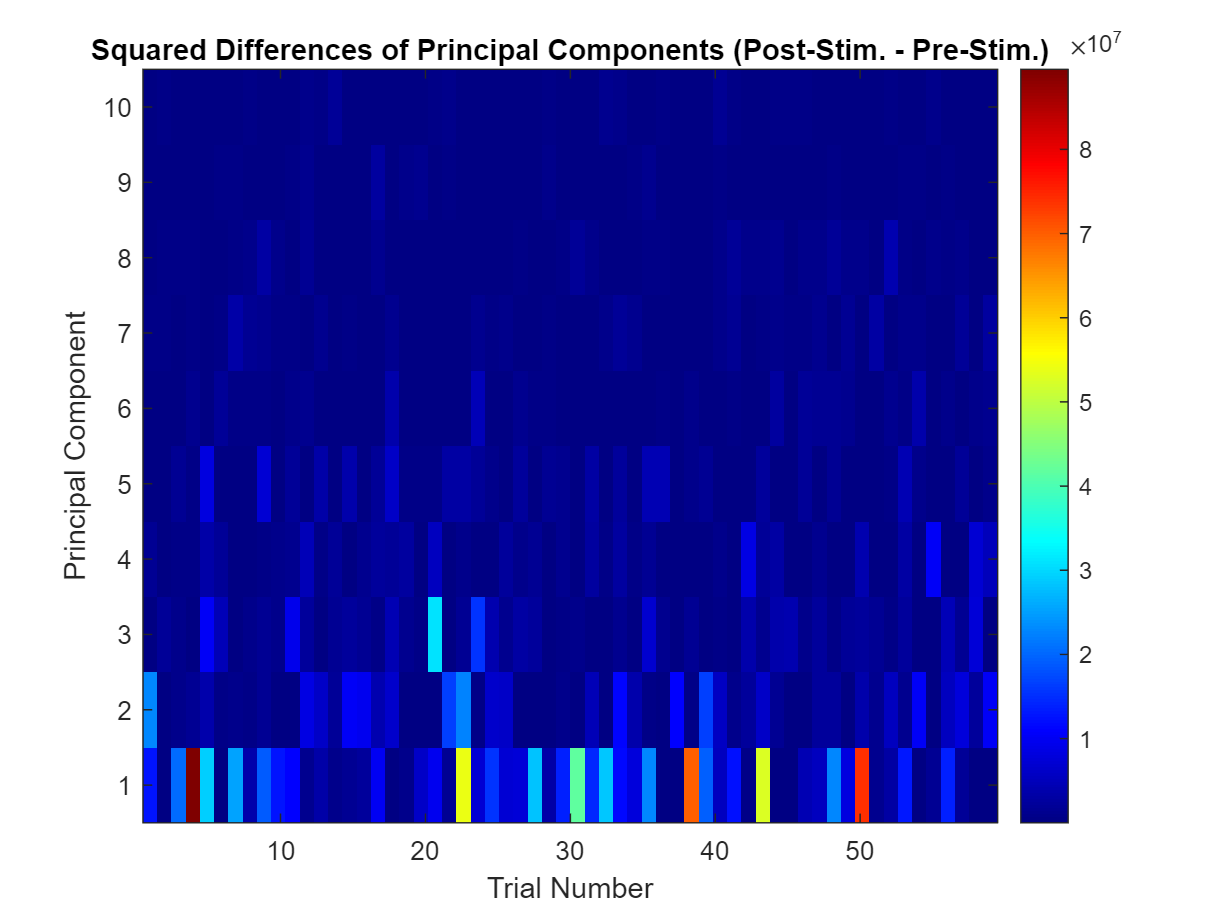

% Plot as heatmap
figure;
imagesc(1:59, 1:10, pc_diff_squared(:,1:10)'); % Transpose so PCs are on the y-axis
colorbar;
xlabel('Trial Number');
ylabel('Principal Component');
title('Squared Differences of Principal Components (Post-Stim. - Pre-Stim.)');
set(gca, 'YDir', 'normal'); % Ensure correct orientation
colormap jet;